# CP214 - Lab II

clear 
clc
close all

## Pendulum Example

t_end = 8;
dt = 0.3;
tsamples = 0:dt:t_end;
numS = length(tsamples);
X = zeros(2,numS);

g = 9.81; % m/s^2
l = 1; % m
b = 1; % damping coefficient

% Function Handle
f = @(t,y) [y(2);-g/l*sin(y(1))-b/l*y(2)];

X(:,1) = [pi/3;0]; % initial values

### RK4

tic
for i = 1:numS-1
    k_1 = dt*f(tsamples(i),X(:,i));
    k_2 = dt*f(tsamples(i) + dt/2, X(:,i) + k_1/2);
    k_3 = dt*f(tsamples(i) + dt/2, X(:,i) + k_2/2);
    k_4 = dt*f(tsamples(i) + dt  , X(:,i) + k_3);
    X(:,i+1) = X(:,i) + (k_1 + 2*k_2 + 2*k_3 + k_4)/6; % Find nect value
end
toc

Elapsed time is 0.010706 seconds.


### **ode45**

tic
[t,X_ode] = ode45(f,[tsamples(1) tsamples(end)], X(:,1));
toc

Elapsed time is 0.010321 seconds.


### Plots

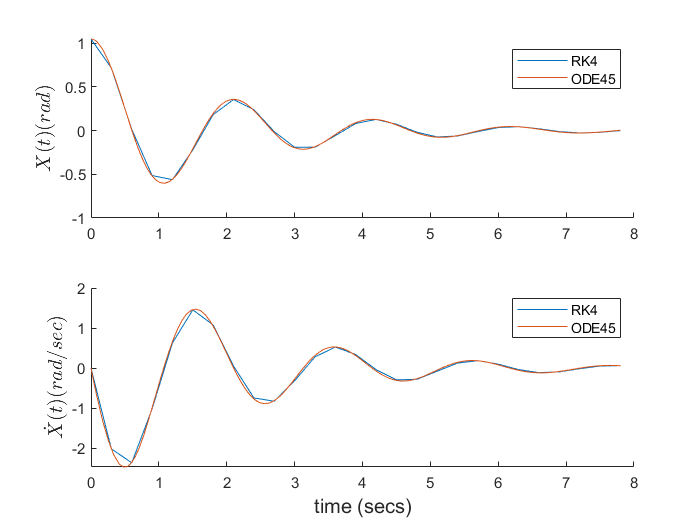

fig = figure();
for i = 1:2
    subplot(2,1,i)
    hold on
    plot(tsamples,X(i,:),"DisplayName","RK4")
    plot(t,X_ode(:,i),"DisplayName","ODE45")
    legend()
    if i == 1
       ylabel("$X(t) (rad)$" , "Interpreter", "latex", "FontSize", 12, "FontWeight","bold") 
    else
        ylabel("$\dot{X}(t) (rad/sec)$", "Interpreter", "latex" ,"FontSize",12, "FontWeight","bold")
    end
end
xlabel("time (secs)", "FontSize",12)

% Theta vs Theta_dot (Phase portrait)
figure
plot(X(1,:),X(2,:)); hold on;
plot(X_ode(:,1),X_ode(:,2));